# Lab - Boundary value problems 1

**Topics: **analytical solution for BVPs, shooting method for linear equations, shooting method for non-linear equations

## Water table height

clear, clc

Given: $K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$

Solve for the height of the water table for x = 0 to 1000 m where h(0)=10 m and h(1000)=5 m. Use the following parameters: K=1 m/d and N=0.0001 m/d. Use the average of the boundary conditions as the average height ($\bar{h}$).

### Set up variables

x0 = 0;
xf = 1000;
K = 1;
N = .0001;
h0 = 10;
hf = 5;
hbar = (h0+hf)/2;

### **Analytical solution**


$$K\bar{h} \;\frac{d^2 h}{{dx}^2 }+N=0$$


syms h(x)
Dh = diff(h);
ode = K*hbar*diff(h, x, 2) + N == 0;

cond1 = h(x0) == h0;
cond2 = h(xf) == hf;
conds = [cond1, cond2];

solution(x) = dsolve(ode, conds)

$$solution(x) = -\frac{x^{2}}{150000}+\frac{x}{600}+10$$

### System of ODEs


$$\frac{d}{\textrm{dx}}\left\lbrack \begin{array}{c}
h\\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u\\
-\frac{N}{K\bar{h} }
\end{array}\right\rbrack$$


dH = @(x, H) [H(2); -N/(K*hbar)];

### 1st shot

z1 = 0;
[x1 H1] = ode45(dH, [x0 xf], [h0 z1]);
H1_end = H1(end, 1)

H1_end = 3.3333

### 2nd shot

z2 = .001;
[x2 H2] = ode45(dH, [x0 xf], [h0, z2]);
H2_end = H2(end, 1)

H2_end = 4.3333

### Linear interpolation to find dh/dx


$$g_f =g_1 +\frac{g_2 -g_1 }{T_2 -T_1 }\left(T_f -T_1 \right)$$


z_act = z1 + (z2-z1)/(H2_end-H1_end)*(hf-H1_end)

z_act = 0.0017

### Solution

[x, H] = ode45(dH, [x0 xf], [h0, z_act]);
H_end = H(end, 1)

H_end = 5.0000

check = H_end - hf

check = 8.8818e-16

### Plot

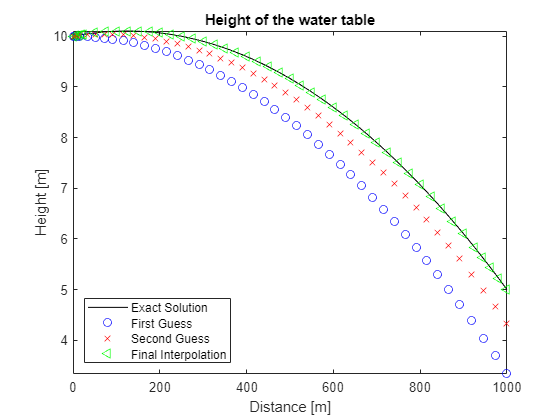

figure()
fplot(solution, [x0 xf], "k")
hold on
plot(x1, H1(:,1), "bo", x2, H2(:,1), "rx", x, H(:,1), "g<")
hold off
title("Height of the water table")
xlabel("Distance [m]")
ylabel("Height [m]")
legend("Exact Solution", "First Guess", "Second Guess", "Final Interpolation", "location", "southwest")

## Non-linear BVP

clear, clc

Given: $\frac{d^2 y}{{\textrm{dx}}^2 }=4+0\ldotp 25x^3 -0\ldotp 125y\;\frac{\textrm{dy}}{\textrm{dx}}$

Solve for y in the range of $1\le x\le 3$where $y\left(1\right)=17$ and $y\left(3\right)=\frac{43}{3}$

### Set up variables

x0 = 1;
xf = 3;
y0 = 17;
yf = 43/3;

### **Analytical solution**


$$y\left(x\right)=x^2 +\frac{16}{x}$$


x_exact = linspace(x0, xf);
y_exact = x_exact.^2 + 16./x_exact;

% syms y(x)
% Dy = diff(y);
% ode = 4 + 0.25*x^3 - 0.125*y*Dy - diff(y, x, 2) == 0;
% 
% cond1 = y(x0) == 17;
% cond2 = y(xf) == 43/3;
% conds = [cond1, cond2];
% 
% solution(x) = dsolve(ode, conds)

### Find where residual = 0

za = fzero(@shooting_res, -10)

za = -13.9998

### Solution

[x, Y] = ode45(@dYdx, [x0 xf], [y0, za]);
Y_end = Y(end, 1)

Y_end = 14.3333

### Plot y

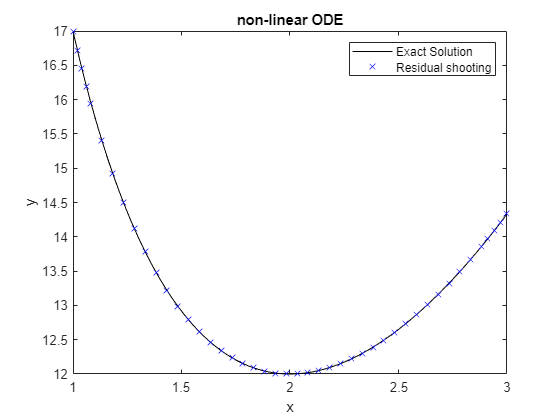

figure()
% fplot()
plot(x_exact, y_exact, "k", x, Y(:,1), "bx")
xlabel("x")
ylabel("y")
title("non-linear ODE")
legend("Exact Solution", "Residual shooting", "location", "northeast")

## Helper functions

### Non-linear system function


$$\frac{d}{\textrm{dx}}\left\lbrack \begin{array}{c}
y\\
v
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v\\
4+0\ldotp 25x^3 -0\ldotp 125\textrm{yv}
\end{array}\right\rbrack$$


function dY = dYdx(x, Y)
dY = [Y(2);
      4 + .25*x^3 - .125*Y(1)*Y(2)];
end

### Residual function

Solve for y in the range of $1\le x\le 3$ where $y\left(1\right)=17$ and $y\left(3\right)=\frac{43}{3}$

function r = shooting_res(za)
[x, Y] = ode45(@dYdx, [1 3], [17 za]);
r = Y(end, 1) - 43/3;
end